M130 Lab 3

Start by checking the image properties of your assigned image and loading it into MATLAB

%Load your image
%Remember to use imfinfo to see what the image size is
%create the placeholder variable with 'zeros' and use a 
%for loop to read in the data (1 point)

info = imfinfo('Image_9.tif'); 
length(info) %find out how many pages 

ans = 104

info(1).Width

ans = 1042

info(1).Height 

ans = 221

info(1).BitDepth

ans = 8

info(1).ColorType

ans = 'grayscale'

disp("The size of image is 1042x221, with 104 pages")

The size of image is 1042x221, with 104 pages



img = zeros(info(1).Height, info(1).Width, length(info), 'uint8'); 
for i = 1:length(info)
    img(:,:,i) = imread('Image_9.tif', i); 
end 

size(img) %checks out

ans =          221        1042         104


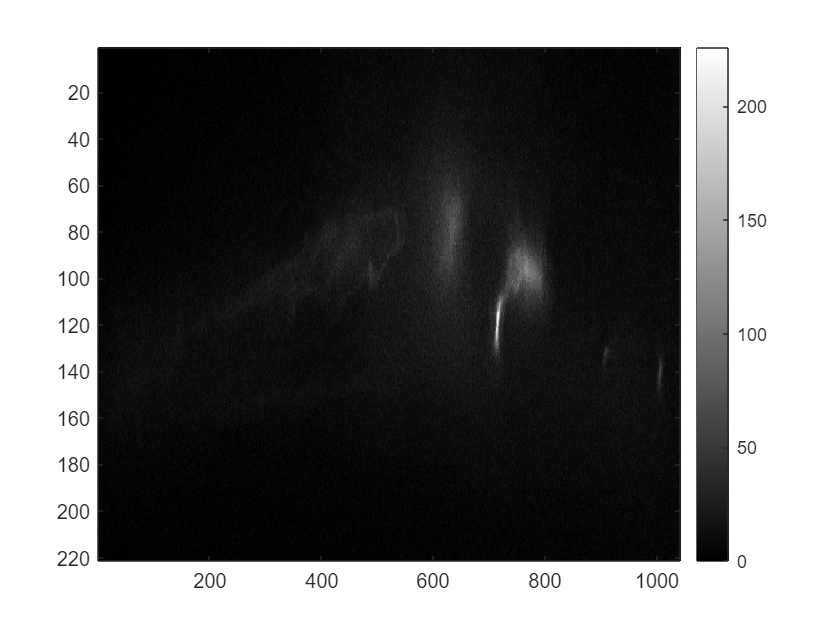

%Compute a max projection of your image and display it (1 point)

imagesc(img(:,:,1)) % display specific page of the image
colormap gray %legend that interprets pixel brightness
colorbar 

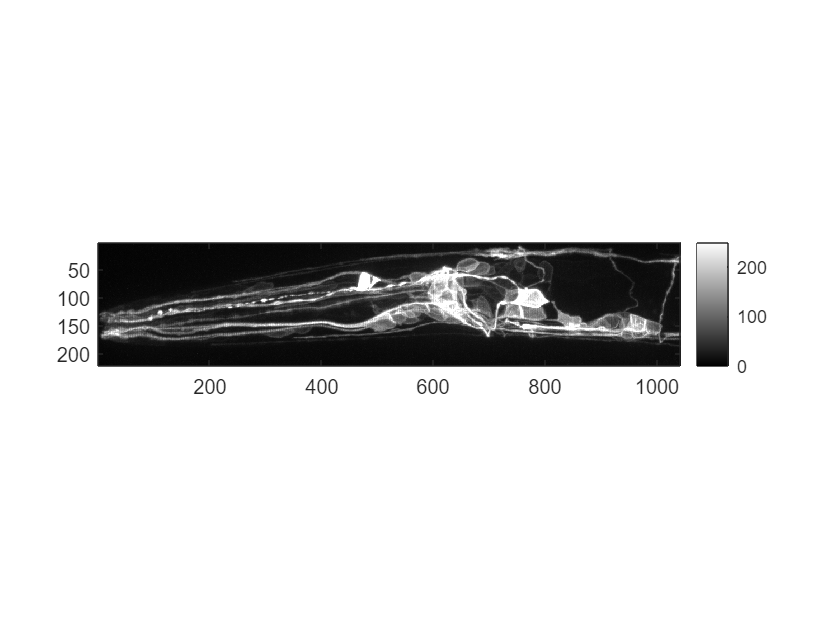


max_proj = max(img,[],3);
figure
imagesc(max_proj,[0,250])
colormap gray
axis image
colorbar

%above code is for max projection, I just wanted to see it in sliceviewer

%sliceViewer(img, "DisplayRange", [0, 250])

%Compute the Fourier Transform of your max projection image and display the
%real values of the Fourier Transform
%Remember that the FT image has to be rearranged to display correctly using
%the fftshift command    (3 point)

%We use max projection image as original image 

ft = fft2(max_proj);
ft_shift = fftshift(ft); 
disp('for better visualization, shift 0-frequency component to the center')

for better visualization, shift 0-frequency component to the center


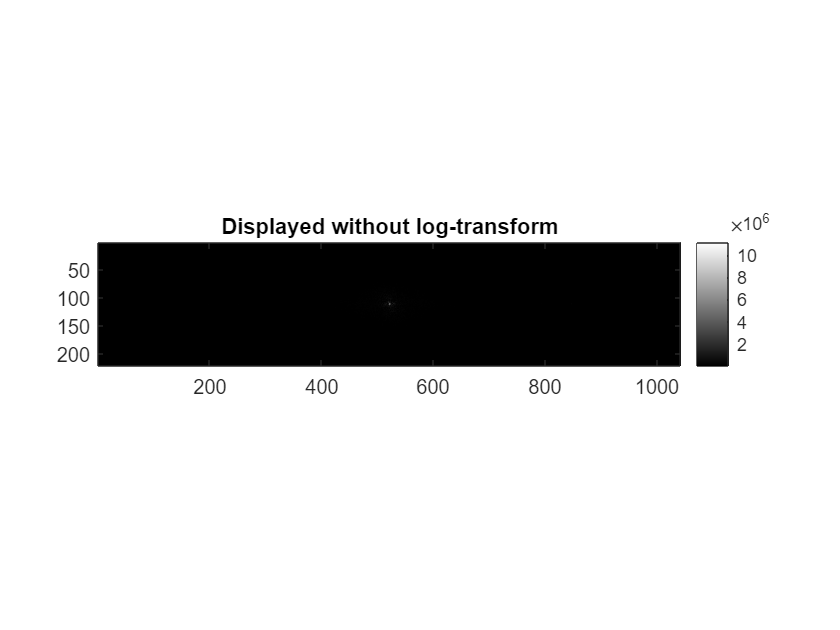


figure
imagesc(abs(ft_shift))

colormap gray
axis image
colorbar
title("Displayed without log-transform")

disp('We notice a single bright dot at 550/100')

We notice a single bright dot at 550/100


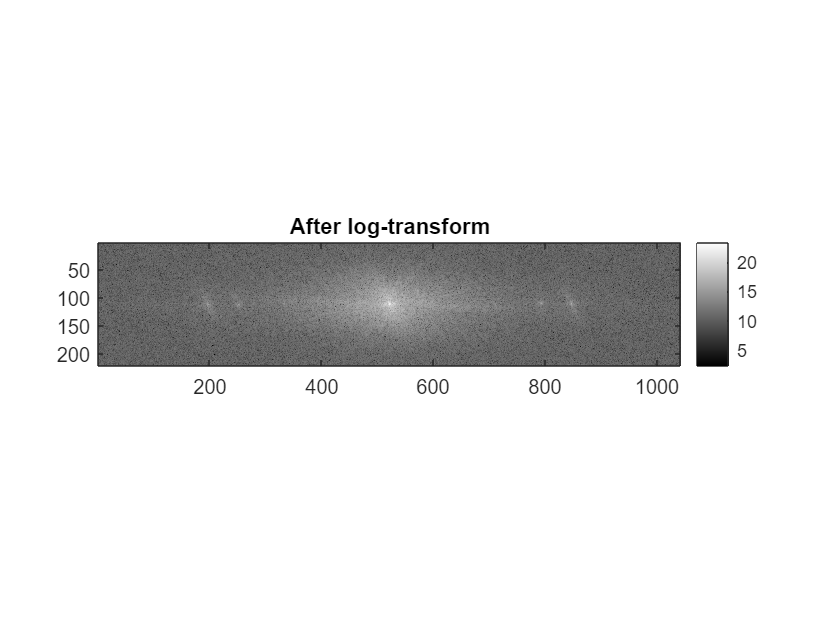

figure
imagesc(log2(1+abs(ft_shift))) 
colormap gray
axis image
colorbar
title("After log-transform")

disp(['After we have transformed in the log domain, we can better visualize the smaller values'])

After we have transformed in the log domain, we can better visualize the smaller values


disp('especially around the high-frequency regions. We have brought down high intensity and brought up low intensity')

especially around the high-frequency regions. We have brought down high intensity and brought up low intensity


disp('We add 1 to avoid log(0), we chose 1 because it is a small number')

We add 1 to avoid log(0), we chose 1 because it is a small number


Compare your image and its Fourier Transform. Are there any features of your image that you can see reflected in the Fourier Transform? Think specifically about the orientation of objects in the image, and of the presence or absence of directional edges in the image. Type your observations here:

For better visualization, we shift 0-frequency component to the center. The original value displayed without log-transform is not informative. We see a bright dot in the middle of the zero axis, and it represents the overall brightness of the image. 

The image I was given has a lot of high frequency-low frequency changes vertically, but not as obvious (thin lines in the embryo) changes horizontally. This means that signal frequencies follow the cosine wave rule (Lecture 6) where the original image has more vertical component and the Fourier image has more horizontal components/patterns on both sides (two bright dots lined up symmetrically). 

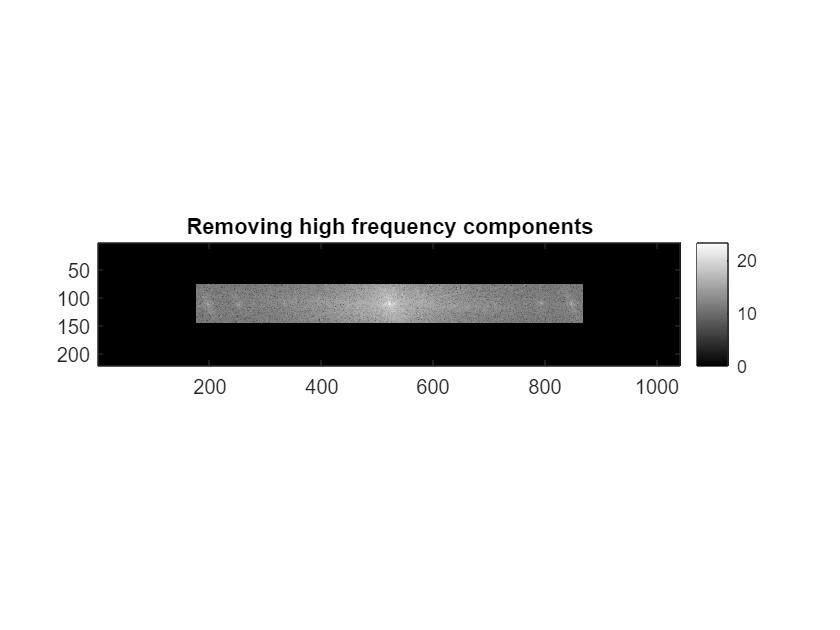

%Using indexing like the example from Lecture 5 set an OUTER region
%of the Fourier Transform to 0, compute the ifft and display it (2 points)

ft_2 = ft_shift; % copy the ft result to another variable

ft_2(1:75, :) = 0; % set the first 50 rows to 0
ft_2(end-75:end, :) = 0; % set the last 50 rows to 0
ft_2(:, 1:175) = 0; % set the first 150 columns to 0
ft_2(:, end-175:end) = 0; % set the last 150 columns to 0

%set fourier domain to convert 0 of peripheral regions, set boundaries


figure
imagesc(log2(1+abs(ft_2)))
colormap gray
axis image
colorbar
title("Removing high frequency components") % In this log transformed image, the high frequencies are the non-bright spots

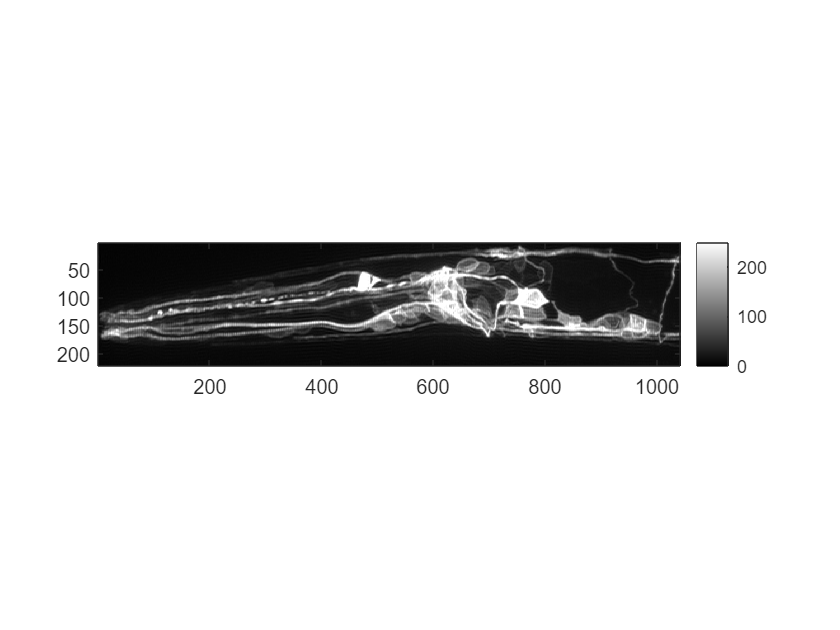

img_2 = ifft2(ifftshift(ft_2));
imagesc(abs(img_2),[0,250]) % change the thresholds for the best visualization of your own image
colormap gray
axis image
colorbar

%Using indexing like the example from Lecture 5 set an INNER region
%of the Fourier Transform to 0, compute the ifft and display it (2 points)

ft_1 = ft_shift; % copy the ft result to another variable
center_x =  uint16((info(1).Height+1)/2) 

center_x = uint16
111


center_y =  uint16((info(1).Width +1)/2) % compute the coordinate of the center

center_y = uint16
522


ft_1(center_x-15:center_x+15, center_y-10:center_y+10) = 0; % set the central region to 0
disp('this covers up the central region almost in entirety')

this covers up the central region almost in entirety


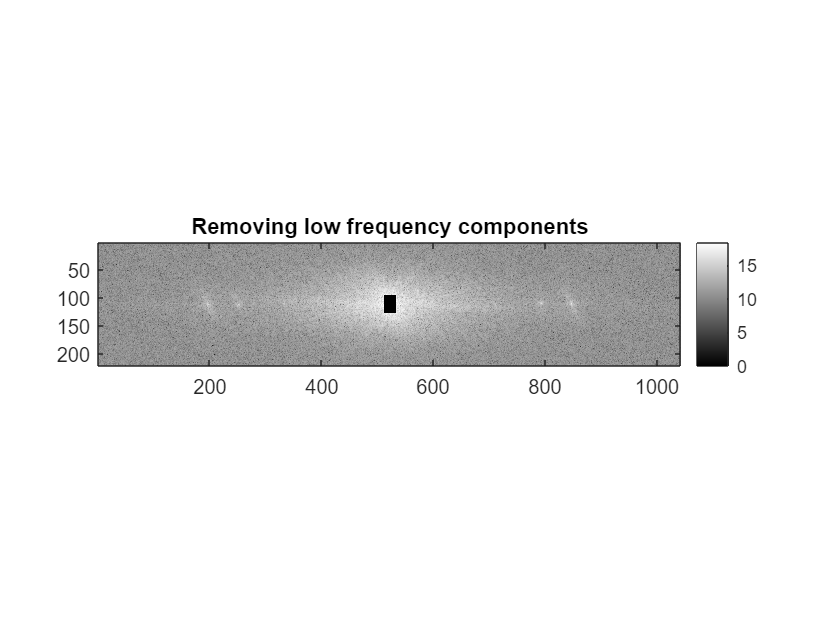


figure
imagesc(log2(1+abs(ft_1)))
colormap gray
axis image
colorbar
title("Removing low frequency components")

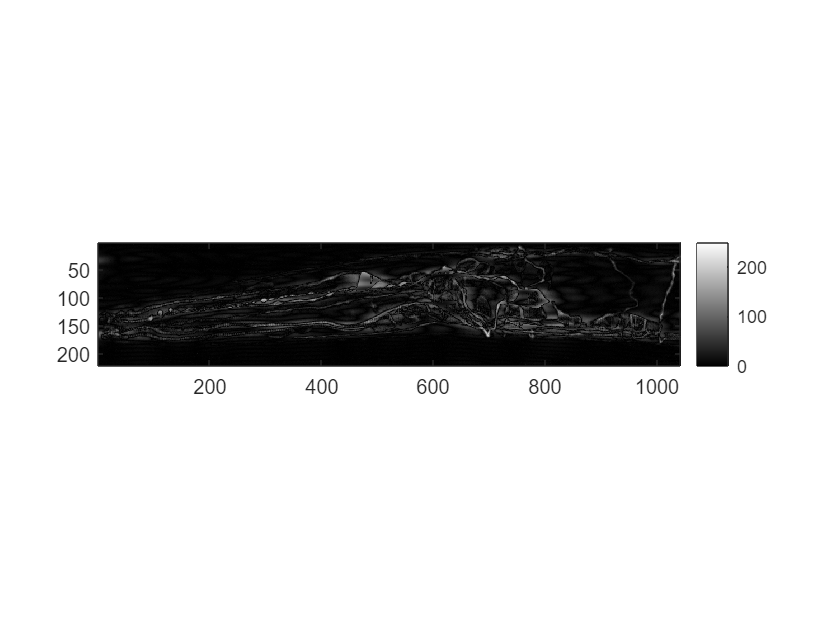


img_1 = ifft2(ifftshift(ft_1)); %shift it back to original and then inverse
imagesc(abs(img_1),[0,250]) % change the thresholds for the best visualization of your own image
colormap gray
axis image
colorbar

What's different about the two "filtered" images? What was lost vs preserved in each? Type your observations here:

The first image is very similar to the max-projection original image, with little to no noticeable differences. We can deduce that our original image doesn't have a lot of high-frequency signals. However, the second filtered image where we removed the low frequency components and then performed fourier transformaiton dimmed the image considerably and extracted a lot of brightness and structure of the image. 

In the second image, the overall structure is lost and we are able to preserve the outline of the embryo (in image) only. The interior seems to have been hollowed out, and this is a feature of fourier transformations. We have been trying to mitigate noise by zeroing out frequencies. 

In an image where two objects have sharp features, we use low-frequency compression to mitigate noise. This is because sharp boundaries are created from high-frequency sin waves, and less-sharp boundaries are created from low-frequency sin waves. This is what photoshop does in the blurring tool to reduce transition contrasts. 

Share some feedback, what's working for you? what's not working for you? what concepts are you struggling with the most? (1 point)

So far, everything seems to be working fine. I am still struggling to understand what Professor means when he says that "spatial averaging crisis is averted by using fourier transform". Why is it a crisis? And how is Fourier transform averting this crisis? 